**3. Considere duas variáveis aleatórias relativas às classificações de uma turma de 120 alunos em duas Unidades Curriculares (ex: MPEI e POO). Designemos essas variáveis discretas por N1 e N2.**

**(a)** Gere N1 e N2 para que, antes de arredondamento para o valor inteiro mais próximo, tenham uma distribuição Normal com as seguintes médias e variâncias: média de N1 igual a 14; média de N2 20% superior a N1; variâncias iguais a 1/4 da média.

N1_media = 14;
N1_var = N1_media / 4;
N1_desvio = sqrt(N1_var);

N2_media = 1.2 * N1_media;
N2_var = N2_media / 4;
N2_desvio = sqrt(N2_var);

N1 = round(normrnd(N1_media, N1_desvio, 1, 120))

N1 =     13    16    13    17    13    13    14    16    16    13    17    13    16    13    14    10    14    13    15    16    15    13    17    11    13    16    13    16    12    14    13    13    13    15    11    14    11    13    14    16    12    14    16    12    11    15    13    17    12    14


N2 = round(normrnd(N2_media, N2_desvio, 1, 120))

N2 =     16    17    16    20    15    16    14    13    19    16    17    15    17    16    17    15    16    20    18    17    15    17    12    19    16    17    21    18    19    19    16    17    17    16    16    13    17    16    13    16    14    17    15    18    16    18    18    15    16    13


**(b)** Obtenha e represente graficamente a função probabilidade de massa conjunta de N1 e N2.

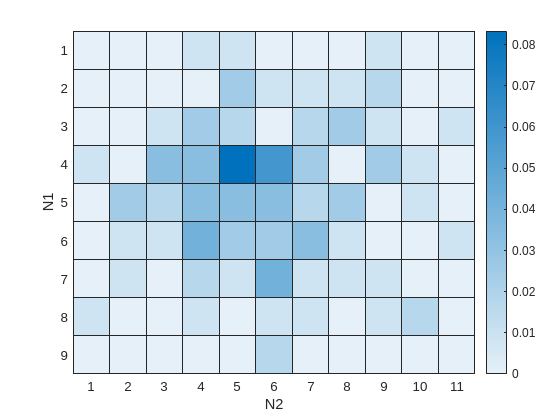

joint_dist = histcounts2(N1, N2, 'Normalization', 'probability'); % SEE THIS SHIT?

heatmap(joint_dist, 'XLabel', 'N2', 'YLabel', 'N1');

**(c)** Qual o valor do coeficiente de correlação entre N1 e N2 ?

% Calculate the correlation coefficient
corr_coef = corr(N1, N2);
disp('Correlation coefficient between N1 and N2:');
disp(corr_coef);


**(d)** N1 e N2 são independentes ?

Two random variables are independent if their joint distribution equals the product of their marginal distributions. In MATLAB, you can calculate the marginal distributions of N1N_1N1� and N2N_2N2� and compare them with the joint distribution.

You can test for independence by checking if the correlation coefficient is close to zero, which would indicate low linear dependence. However, more complex dependence might require additional statistical tests.